%% ================================================================
%  RIS ARRAY VALIDATION AND ARRAY-SIZE SELECTION
%
%  Purpose:
%  1. Validate analytical RIS model against 2x2 HFSS
%  2. Compare ideal 180-degree RIS with actual HFSS unit-cell response
%  3. Test 3x3, 4x4, 5x5, 6x6, 7x7 and 8x8 arrays
%  4. Determine which array should be designed in HFSS
%  5. Select candidate for hardware fabrication
%
%  Frequency       = 2.45 GHz
%  Unit-cell pitch = 60 mm
%  Steering plane  = Phi = 0 degrees
%
% ================================================================

clear;
clc;
close all;

%% ================================================================
% 1. BASIC PARAMETERS
% ================================================================

f = 2.45e9;
c = 299792458;

lambda = c/f;
k = 2*pi/lambda;

dx = 60e-3;
dy = 60e-3;

fprintf('\n');
fprintf('============================================================\n');

fprintf('       RIS ARRAY VALIDATION STUDY\n');

       RIS ARRAY VALIDATION STUDY


fprintf('============================================================\n');


fprintf('Frequency       = %.3f GHz\n',f/1e9);

Frequency       = 2.450 GHz


fprintf('Wavelength      = %.3f mm\n',lambda*1000);

Wavelength      = 122.364 mm


fprintf('Unit-cell pitch = %.2f mm\n',dx*1000);

Unit-cell pitch = 60.00 mm


fprintf('dx/lambda       = %.4f\n',dx/lambda);

dx/lambda       = 0.4903


fprintf('dy/lambda       = %.4f\n',dy/lambda);

dy/lambda       = 0.4903



%% ================================================================
% 2. ACTUAL HFSS UNIT-CELL RESPONSE
% ================================================================
%
% Values extracted from your HFSS simulation at 2.45 GHz.
%
% ON:
% S11 = -1.4661 dB
% Phase = +148.922 degrees
%
% OFF:
% S11 = -1.3114 dB
% Phase = -70.2555 degrees
%
% ================================================================

S11_ON_dB  = -1.4661;
S11_OFF_dB = -1.3114;

phase_ON_deg  = +148.922;
phase_OFF_deg = -70.2555;

% Convert S11 magnitude from dB
mag_ON  = 10^(S11_ON_dB/20);
mag_OFF = 10^(S11_OFF_dB/20);

% Complex reflection coefficients
Gamma_ON_realistic = ...
    mag_ON * exp(1j*deg2rad(phase_ON_deg));

Gamma_OFF_realistic = ...
    mag_OFF * exp(1j*deg2rad(phase_OFF_deg));

% Actual phase separation
deltaPhase_realistic = ...
    mod(phase_ON_deg - phase_OFF_deg + 180,360) - 180;

fprintf('\n');
fprintf('------------------------------------------------------------\n');

------------------------------------------------------------


fprintf('ACTUAL HFSS UNIT-CELL RESPONSE\n');

ACTUAL HFSS UNIT-CELL RESPONSE


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------



fprintf('ON  : |Gamma| = %.6f, Phase = %+8.3f deg\n', ...
    mag_ON, phase_ON_deg);

ON  : |Gamma| = 0.844685, Phase = +148.922 deg



fprintf('OFF : |Gamma| = %.6f, Phase = %+8.3f deg\n', ...
    mag_OFF, phase_OFF_deg);

OFF : |Gamma| = 0.859864, Phase =  -70.255 deg



fprintf('Actual phase separation = %.3f deg\n', ...
    abs(deltaPhase_realistic));

Actual phase separation = 140.822 deg



%% ================================================================
% 3. IDEAL 180-DEGREE REFERENCE
% ================================================================

Gamma_ON_ideal  = 1;
Gamma_OFF_ideal = -1;

phase_ON_ideal_deg  = 0;
phase_OFF_ideal_deg = 180;

fprintf('\n');
fprintf('------------------------------------------------------------\n');

------------------------------------------------------------


fprintf('IDEAL RIS REFERENCE\n');

IDEAL RIS REFERENCE


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------



fprintf('|Gamma_ON|  = 1\n');

|Gamma_ON|  = 1


fprintf('|Gamma_OFF| = 1\n');

|Gamma_OFF| = 1


fprintf('Phase separation = 180 degrees\n');

Phase separation = 180 degrees



%% ================================================================
% 4. GRATING-LOBE / SPACING CHECK
% ================================================================

spacingRatio = dx/lambda;

fprintf('\n');
fprintf('------------------------------------------------------------\n');

------------------------------------------------------------


fprintf('ELEMENT SPACING CHECK\n');

ELEMENT SPACING CHECK


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------



fprintf('d/lambda = %.4f\n',spacingRatio);

d/lambda = 0.4903



if spacingRatio <= 0.5
    fprintf('RESULT: SAFE spacing (d <= lambda/2)\n');
    fprintf('No spacing-induced grating lobes are expected\n');
    fprintf('over the visible scan range.\n');
else
    fprintf('WARNING: d > lambda/2\n');
    fprintf('Grating-lobe risk exists for off-boresight steering.\n');
end

RESULT: SAFE spacing (d <= lambda/2)


No spacing-induced grating lobes are expected


over the visible scan range.



%% ================================================================
% 5. ARRAY SIZES
% ================================================================

arraySizes = [2 3 4 5 6 7 8];

% Steering angles to investigate
steeringAngles = [0 5 10 15 20 25 30];

numArrays = length(arraySizes);
numAngles = length(steeringAngles);

% Angular observation grid
theta = -90:0.05:90;
thetaRad = deg2rad(theta);

% Search windows
desiredWindow = 10;
guardWindow = 12;

%% ================================================================
% 6. STORAGE
% ================================================================

% Practical HFSS model
desiredAngle_real = zeros(numArrays,numAngles);
globalAngle_real  = zeros(numArrays,numAngles);
steeringError_real = zeros(numArrays,numAngles);
desiredLevel_real = zeros(numArrays,numAngles);
globalPenalty_real = zeros(numArrays,numAngles);
sll_real = zeros(numArrays,numAngles);
hpbw_real = zeros(numArrays,numAngles);

% Ideal model
desiredAngle_ideal = zeros(numArrays,numAngles);
globalAngle_ideal  = zeros(numArrays,numAngles);
steeringError_ideal = zeros(numArrays,numAngles);
desiredLevel_ideal = zeros(numArrays,numAngles);
sll_ideal = zeros(numArrays,numAngles);
hpbw_ideal = zeros(numArrays,numAngles);

%% ================================================================
% 7. MAIN ARRAY SWEEP
% ================================================================

for s = 1:numAngles

    targetAngle = steeringAngles(s);
    targetRad = deg2rad(targetAngle);

    fprintf('\n');
    fprintf('============================================================\n');
    fprintf('TARGET ANGLE = %+5.1f degrees\n',targetAngle);
    fprintf('============================================================\n');

    for a = 1:numArrays

        N = arraySizes(a);

        % --------------------------------------------------------
        % Element coordinates
        % --------------------------------------------------------

        x = ((0:N-1) - (N-1)/2) * dx;
        y = ((0:N-1) - (N-1)/2) * dy;

        % --------------------------------------------------------
        % Desired continuous phase profile
        % --------------------------------------------------------

        desiredPhase = -k*x*sin(targetRad);

        % ========================================================
        % PRACTICAL HFSS MODEL
        % ========================================================

        state_real = zeros(N,N);

        for m = 1:N

            phi_required = desiredPhase(m);

            % Circular phase error
            errorON = abs(angle( ...
                exp(1j*(phi_required - ...
                angle(Gamma_ON_realistic)))));

            errorOFF = abs(angle( ...
                exp(1j*(phi_required - ...
                angle(Gamma_OFF_realistic)))));

            if errorON <= errorOFF
                state_real(m,:) = 1;
            else
                state_real(m,:) = 0;
            end

        end

        % --------------------------------------------------------
        % Calculate practical array factor
        % --------------------------------------------------------

        AF_real = zeros(size(theta));

        for m = 1:N

            for n = 1:N

                if state_real(m,n) == 1
                    Gamma = Gamma_ON_realistic;
                else
                    Gamma = Gamma_OFF_realistic;
                end

                spatialPhase = ...
                    k*x(m)*sin(thetaRad);

                AF_real = AF_real + ...
                    Gamma .* exp(1j*spatialPhase);

            end

        end

        % --------------------------------------------------------
        % Normalize
        % --------------------------------------------------------

        AFmag = abs(AF_real);
        AFmag = AFmag ./ max(AFmag);

        AFdB = 20*log10(AFmag + eps);

        % --------------------------------------------------------
        % Global strongest beam
        % --------------------------------------------------------

        [globalValue,globalIndex] = max(AFdB);

        globalAngle = theta(globalIndex);

        globalAngle_real(a,s) = globalAngle;

        % --------------------------------------------------------
        % Desired beam
        % --------------------------------------------------------

        desiredMask = ...
            theta >= targetAngle-desiredWindow & ...
            theta <= targetAngle+desiredWindow;

        desiredIndices = find(desiredMask);

        [desiredValue,localIndex] = ...
            max(AFdB(desiredIndices));

        desiredIndex = desiredIndices(localIndex);

        desiredAngle = theta(desiredIndex);

        desiredAngle_real(a,s) = desiredAngle;

        steeringError_real(a,s) = ...
            desiredAngle-targetAngle;

        desiredLevel_real(a,s) = desiredValue;

        % --------------------------------------------------------
        % Global beam penalty
        %
        % 0 dB  = desired beam is strongest
        % positive = another beam is stronger
        % --------------------------------------------------------

        globalPenalty_real(a,s) = ...
            globalValue - desiredValue;

        % --------------------------------------------------------
        % Sidelobe level
        % --------------------------------------------------------

        sidelobeMask = ...
            theta < targetAngle-guardWindow | ...
            theta > targetAngle+guardWindow;

        sidelobeValues = AFdB(sidelobeMask);

        sll_real(a,s) = max(sidelobeValues);

        % --------------------------------------------------------
        % HPBW
        % --------------------------------------------------------

        hpbw_real(a,s) = ...
            calculateHPBW(theta,AFdB,desiredIndex);

        % ========================================================
        % IDEAL 180-DEGREE MODEL
        % ========================================================

        state_ideal = zeros(N,N);

        for m = 1:N

            phi_required = desiredPhase(m);

            errorON = abs(angle( ...
                exp(1j*(phi_required - ...
                angle(Gamma_ON_ideal)))));

            errorOFF = abs(angle( ...
                exp(1j*(phi_required - ...
                angle(Gamma_OFF_ideal)))));

            if errorON <= errorOFF
                state_ideal(m,:) = 1;
            else
                state_ideal(m,:) = 0;
            end

        end

        % --------------------------------------------------------
        % Ideal array factor
        % --------------------------------------------------------

        AF_ideal = zeros(size(theta));

        for m = 1:N

            for n = 1:N

                if state_ideal(m,n) == 1
                    Gamma = Gamma_ON_ideal;
                else
                    Gamma = Gamma_OFF_ideal;
                end

                spatialPhase = ...
                    k*x(m)*sin(thetaRad);

                AF_ideal = AF_ideal + ...
                    Gamma .* exp(1j*spatialPhase);

            end

        end

        AFmag_ideal = abs(AF_ideal);
        AFmag_ideal = AFmag_ideal ./ max(AFmag_ideal);

        AFdB_ideal = 20*log10(AFmag_ideal + eps);

        % --------------------------------------------------------
        % Ideal global beam
        % --------------------------------------------------------

        [~,globalIndexIdeal] = max(AFdB_ideal);

        globalAngle_ideal(a,s) = ...
            theta(globalIndexIdeal);

        % --------------------------------------------------------
        % Ideal desired beam
        % --------------------------------------------------------

        desiredIndicesIdeal = ...
            find(desiredMask);

        [desiredValueIdeal,localIndexIdeal] = ...
            max(AFdB_ideal(desiredIndicesIdeal));

        desiredIndexIdeal = ...
            desiredIndicesIdeal(localIndexIdeal);

        desiredAngle_ideal(a,s) = ...
            theta(desiredIndexIdeal);

        steeringError_ideal(a,s) = ...
            desiredAngle_ideal(a,s)-targetAngle;

        desiredLevel_ideal(a,s) = ...
            desiredValueIdeal;

        % --------------------------------------------------------
        % Ideal SLL
        % --------------------------------------------------------

        sidelobeValuesIdeal = ...
            AFdB_ideal(sidelobeMask);

        sll_ideal(a,s) = ...
            max(sidelobeValuesIdeal);

        % --------------------------------------------------------
        % Ideal HPBW
        % --------------------------------------------------------

        hpbw_ideal(a,s) = ...
            calculateHPBW(theta,AFdB_ideal,desiredIndexIdeal);

        % --------------------------------------------------------
        % Print practical result
        % --------------------------------------------------------

        fprintf('%2dx%-2d : Desired=%+6.1f | Global=%+6.1f | ', ...
            N,N,desiredAngle,globalAngle);

        fprintf('Error=%+6.1f | Beam=%+6.2f dB | ', ...
            steeringError_real(a,s),desiredValue);

        fprintf('GlobalPenalty=%+5.2f dB | SLL=%+5.2f dB\n', ...
            globalPenalty_real(a,s),sll_real(a,s));

    end
end

TARGET ANGLE =  +0.0 degrees


 2x2  : Desired=  +0.0 | Global=  +0.0 | 

Error=  +0.0 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-0.46 dB


 3x3  : Desired=  +0.0 | Global=  +0.0 | 

Error=  +0.0 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-1.24 dB


 4x4  : Desired=  +0.0 | Global=  +0.0 | 

Error=  +0.0 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-2.39 dB


 5x5  : Desired=  +0.0 | Global=  +0.0 | 

Error=  +0.0 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-3.98 dB


 6x6  : Desired=  +0.0 | Global=  +0.0 | 

Error=  +0.0 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-6.13 dB


 7x7  : Desired=  +0.0 | Global=  +0.0 | 

Error=  +0.0 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-9.09 dB


 8x8  : Desired=  +0.0 | Global=  +0.0 | 

Error=  +0.0 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-12.80 dB


TARGET ANGLE =  +5.0 degrees


 2x2  : Desired=  +0.0 | Global=  +0.0 | 

Error=  -5.0 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-0.16 dB


 3x3  : Desired=  +0.0 | Global=  +0.0 | 

Error=  -5.0 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-0.42 dB


 4x4  : Desired=  +0.0 | Global=  +0.0 | 

Error=  -5.0 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-0.79 dB


 5x5  : Desired=  +0.0 | Global=  +0.0 | 

Error=  -5.0 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-1.28 dB


 6x6  : Desired=  +0.0 | Global=  +0.0 | 

Error=  -5.0 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-1.90 dB


 7x7  : Desired=  -3.8 | Global=  -3.8 | 

Error=  -8.8 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-0.39 dB


 8x8  : Desired=  -2.6 | Global=  -2.6 | 

Error=  -7.6 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-0.98 dB


TARGET ANGLE = +10.0 degrees


 2x2  : Desired=  +0.0 | Global=  +0.0 | 

Error= -10.0 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-0.01 dB


 3x3  : Desired=  +0.0 | Global=  +0.0 | 

Error= -10.0 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-0.04 dB


 4x4  : Desired=  +0.0 | Global= -13.8 | 

Error= -10.0 | Beam= -2.60 dB | 

GlobalPenalty=+2.60 dB | SLL=+0.00 dB


 5x5  : Desired=  +0.0 | Global=  -8.8 | 

Error= -10.0 | Beam= -1.38 dB | 

GlobalPenalty=+1.38 dB | SLL=+0.00 dB


 6x6  : Desired= +16.8 | Global= -10.5 | 

Error=  +6.8 | Beam= -2.98 dB | 

GlobalPenalty=+2.98 dB | SLL=+0.00 dB


 7x7  : Desired= +13.2 | Global=  -8.2 | 

Error=  +3.2 | Beam= -3.38 dB | 

GlobalPenalty=+3.38 dB | SLL=+0.00 dB


 8x8  : Desired= +12.8 | Global=  -8.2 | 

Error=  +2.8 | Beam= -2.79 dB | 

GlobalPenalty=+2.79 dB | SLL=+0.00 dB


TARGET ANGLE = +15.0 degrees


 2x2  : Desired=  +5.0 | Global=  +0.0 | 

Error= -10.0 | Beam= -0.08 dB | 

GlobalPenalty=+0.08 dB | SLL=+0.00 dB


 3x3  : Desired= +25.0 | Global= -23.5 | 

Error= +10.0 | Beam= -3.87 dB | 

GlobalPenalty=+3.87 dB | SLL=+0.00 dB


 4x4  : Desired= +22.5 | Global= -13.8 | 

Error=  +7.5 | Beam= -3.45 dB | 

GlobalPenalty=+3.45 dB | SLL=+0.00 dB


 5x5  : Desired= +21.6 | Global= -13.8 | 

Error=  +6.6 | Beam= -2.51 dB | 

GlobalPenalty=+2.51 dB | SLL=+0.00 dB


 6x6  : Desired= +16.8 | Global= -10.5 | 

Error=  +1.8 | Beam= -2.98 dB | 

GlobalPenalty=+2.98 dB | SLL=+0.00 dB


 7x7  : Desired= +15.2 | Global=  -9.8 | 

Error=  +0.2 | Beam= -2.54 dB | 

GlobalPenalty=+2.54 dB | SLL=+0.00 dB


 8x8  : Desired= +16.8 | Global= +16.8 | 

Error=  +1.8 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-0.18 dB


TARGET ANGLE = +20.0 degrees


 2x2  : Desired= +10.0 | Global=  +0.0 | 

Error= -10.0 | Beam= -0.31 dB | 

GlobalPenalty=+0.31 dB | SLL=+0.00 dB


 3x3  : Desired= +30.0 | Global= -23.5 | 

Error= +10.0 | Beam= -2.94 dB | 

GlobalPenalty=+2.94 dB | SLL=+0.00 dB


 4x4  : Desired= +22.5 | Global= -13.8 | 

Error=  +2.5 | Beam= -3.45 dB | 

GlobalPenalty=+3.45 dB | SLL=+0.00 dB


 5x5  : Desired= +21.6 | Global= -13.8 | 

Error=  +1.6 | Beam= -2.51 dB | 

GlobalPenalty=+2.51 dB | SLL=+0.00 dB


 6x6  : Desired= +23.6 | Global= +23.6 | 

Error=  +3.6 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-0.50 dB


 7x7  : Desired= +20.4 | Global= +20.4 | 

Error=  +0.4 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-0.66 dB


 8x8  : Desired= +19.3 | Global= +19.3 | 

Error=  -0.7 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-0.63 dB


TARGET ANGLE = +25.0 degrees


 2x2  : Desired= +15.0 | Global=  +0.0 | 

Error= -10.0 | Beam= -0.71 dB | 

GlobalPenalty=+0.71 dB | SLL=+0.00 dB


 3x3  : Desired= +35.0 | Global= -23.5 | 

Error= +10.0 | Beam= -2.48 dB | 

GlobalPenalty=+2.48 dB | SLL=+0.00 dB


 4x4  : Desired= +22.5 | Global= -13.8 | 

Error=  -2.5 | Beam= -3.45 dB | 

GlobalPenalty=+3.45 dB | SLL=+0.00 dB


 5x5  : Desired= +31.6 | Global= +31.6 | 

Error=  +6.6 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-0.59 dB


 6x6  : Desired= +23.6 | Global= +23.6 | 

Error=  -1.4 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-0.50 dB


 7x7  : Desired= +29.6 | Global= +29.6 | 

Error=  +4.6 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-0.97 dB


 8x8  : Desired= +23.9 | Global= +23.9 | 

Error=  -1.1 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-1.33 dB


TARGET ANGLE = +30.0 degrees


 2x2  : Desired= +40.0 | Global= -52.9 | 

Error= +10.0 | Beam= -4.38 dB | 

GlobalPenalty=+4.38 dB | SLL=+0.00 dB


 3x3  : Desired= +38.2 | Global= -23.5 | 

Error=  +8.2 | Beam= -2.40 dB | 

GlobalPenalty=+2.40 dB | SLL=+0.00 dB


 4x4  : Desired= +28.8 | Global= -18.3 | 

Error=  -1.2 | Beam= -2.11 dB | 

GlobalPenalty=+2.11 dB | SLL=+0.00 dB


 5x5  : Desired= +31.6 | Global= +31.6 | 

Error=  +1.6 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-0.95 dB


 6x6  : Desired= +33.0 | Global= +33.0 | 

Error=  +3.0 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-1.62 dB


 7x7  : Desired= +29.6 | Global= +29.6 | 

Error=  -0.4 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-0.97 dB


 8x8  : Desired= +27.4 | Global= +27.4 | 

Error=  -2.6 | Beam= +0.00 dB | 

GlobalPenalty=+0.00 dB | SLL=-0.55 dB



%% ================================================================
% 8. CREATE SUMMARY TABLE
% ================================================================
%
% The table evaluates each array over all steering angles.
%
% ================================================================

meanError = zeros(numArrays,1);
maxError = zeros(numArrays,1);
meanPenalty = zeros(numArrays,1);
maxPenalty = zeros(numArrays,1);
meanSLL = zeros(numArrays,1);
passCount = zeros(numArrays,1);

for a = 1:numArrays

    meanError(a) = mean(abs(steeringError_real(a,:)));
    maxError(a) = max(abs(steeringError_real(a,:)));

    meanPenalty(a) = mean(globalPenalty_real(a,:));
    maxPenalty(a) = max(globalPenalty_real(a,:));

    meanSLL(a) = mean(sll_real(a,:));

    % ------------------------------------------------------------
    % PASS CRITERIA
    %
    % 1. Desired beam error <= 3 degrees
    % 2. No competing global beam more than 1 dB stronger
    %
    % This is deliberately not an extremely strict criterion.
    % Final HFSS validation is still required.
    % ------------------------------------------------------------

    good = ...
        abs(steeringError_real(a,:)) <= 3 & ...
        globalPenalty_real(a,:) <= 1;

    passCount(a) = sum(good);

end

totalAngles = numAngles;

passPercent = ...
    100*passCount/totalAngles;

%% ================================================================
% 9. ARRAY SIZE RECOMMENDATION
% ================================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('ARRAY SIZE SUMMARY\n');

ARRAY SIZE SUMMARY


fprintf('============================================================\n');


fprintf('\n');
fprintf(' Array | Elements | Mean Error | Max Error | Mean Penalty | ');

 Array | Elements | Mean Error | Max Error | Mean Penalty | 

fprintf('Pass %% | Recommendation\n');

Pass % | Recommendation



fprintf('------------------------------------------------------------\n');

------------------------------------------------------------



for a = 1:numArrays

    N = arraySizes(a);

    if passPercent(a) >= 70 && maxError(a) <= 5

        recommendation = 'GOOD CANDIDATE';

    elseif passPercent(a) >= 40

        recommendation = 'MARGINAL';

    else

        recommendation = 'NOT RECOMMENDED';

    end

    fprintf('%4dx%-2d | %8d | %9.2f | %9.2f | %12.2f | %6.1f | %s\n', ...
        N,N,N*N,meanError(a),maxError(a), ...
        meanPenalty(a),passPercent(a),recommendation);

end

   2x2  |        4 |      7.86 |     10.00 |         0.78 |   14.3 | NOT RECOMMENDED
   3x3  |        9 |      7.61 |     10.00 |         1.67 |   14.3 | NOT RECOMMENDED
   4x4  |       16 |      4.10 |     10.00 |         2.15 |   14.3 | NOT RECOMMENDED
   5x5  |       25 |      4.50 |     10.00 |         0.91 |   28.6 | NOT RECOMMENDED
   6x6  |       36 |      3.08 |      6.75 |         0.85 |   28.6 | NOT RECOMMENDED
   7x7  |       49 |      2.53 |      8.85 |         0.85 |   42.9 | MARGINAL
   8x8  |       64 |      2.37 |      7.65 |         0.40 |   71.4 | MARGINAL


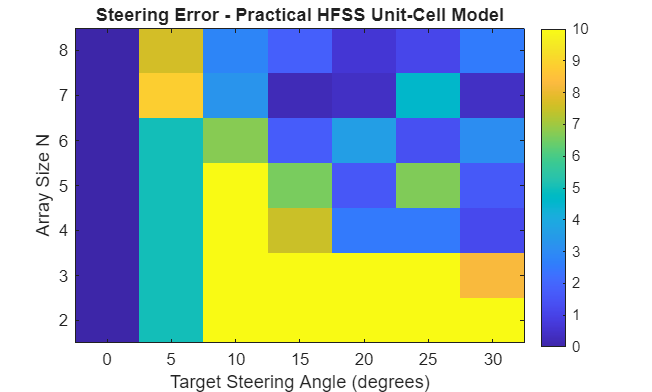


%% ================================================================
% 10. ERROR HEATMAP
% ================================================================

figure;

imagesc(steeringAngles,arraySizes, ...
    abs(steeringError_real));

set(gca,'YDir','normal');

colorbar;

xlabel('Target Steering Angle (degrees)');
ylabel('Array Size N');

title('Steering Error - Practical HFSS Unit-Cell Model');

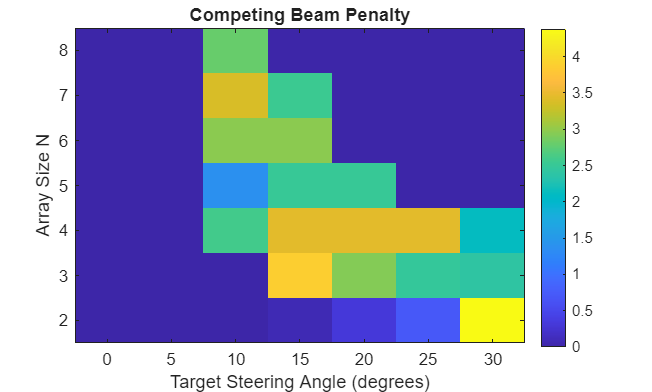


%% ================================================================
% 11. GLOBAL BEAM PENALTY HEATMAP
% ================================================================

figure;

imagesc(steeringAngles,arraySizes, ...
    globalPenalty_real);

set(gca,'YDir','normal');

colorbar;

xlabel('Target Steering Angle (degrees)');
ylabel('Array Size N');

title('Competing Beam Penalty');

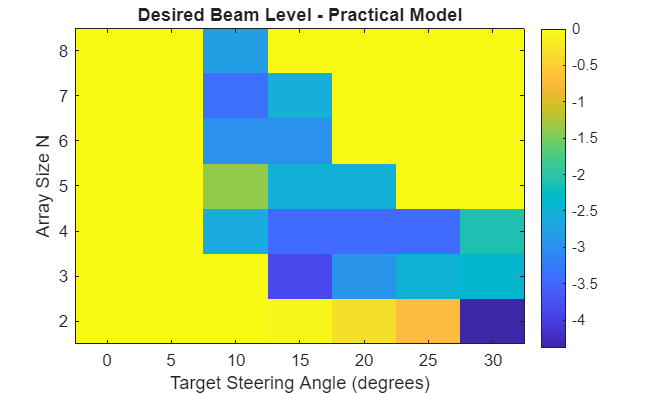


%% ================================================================
% 12. DESIRED BEAM LEVEL HEATMAP
% ================================================================

figure;

imagesc(steeringAngles,arraySizes, ...
    desiredLevel_real);

set(gca,'YDir','normal');

colorbar;

xlabel('Target Steering Angle (degrees)');
ylabel('Array Size N');

title('Desired Beam Level - Practical Model');

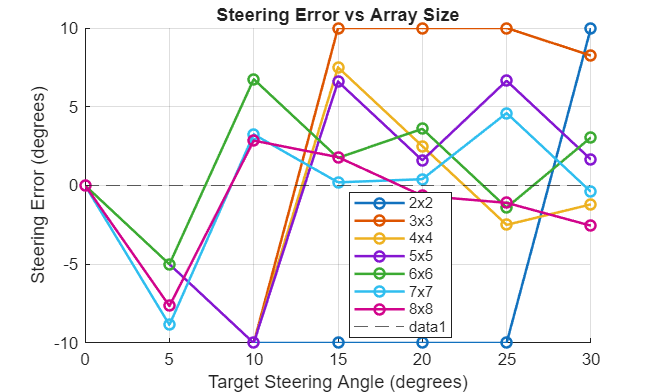


%% ================================================================
% 13. STEERING ERROR VS ARRAY SIZE
% ================================================================

figure;

hold on;

for a = 1:numArrays

    plot(steeringAngles, ...
        steeringError_real(a,:), ...
        '-o', ...
        'LineWidth',1.5, ...
        'DisplayName',sprintf('%dx%d', ...
        arraySizes(a),arraySizes(a)));

end

yline(0,'--');

grid on;

xlabel('Target Steering Angle (degrees)');
ylabel('Steering Error (degrees)');

title('Steering Error vs Array Size');

legend('Location','best');

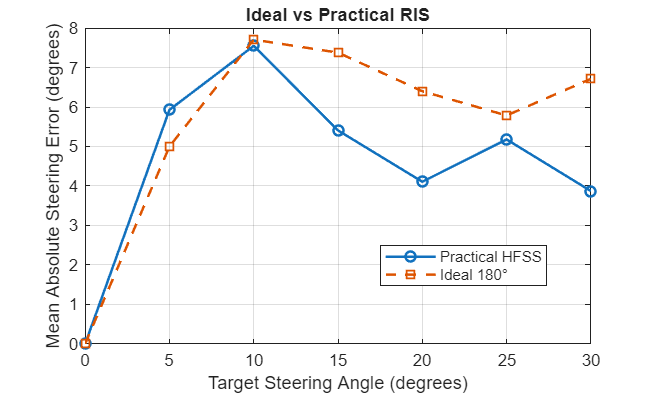


%% ================================================================
% 14. PRACTICAL VS IDEAL PERFORMANCE
% ================================================================

figure;

plot(steeringAngles, ...
    mean(abs(steeringError_real),1), ...
    '-o', ...
    'LineWidth',1.5, ...
    'DisplayName','Practical HFSS');

hold on;

plot(steeringAngles, ...
    mean(abs(steeringError_ideal),1), ...
    '--s', ...
    'LineWidth',1.5, ...
    'DisplayName','Ideal 180°');

grid on;

xlabel('Target Steering Angle (degrees)');
ylabel('Mean Absolute Steering Error (degrees)');

title('Ideal vs Practical RIS');

legend('Location','best');

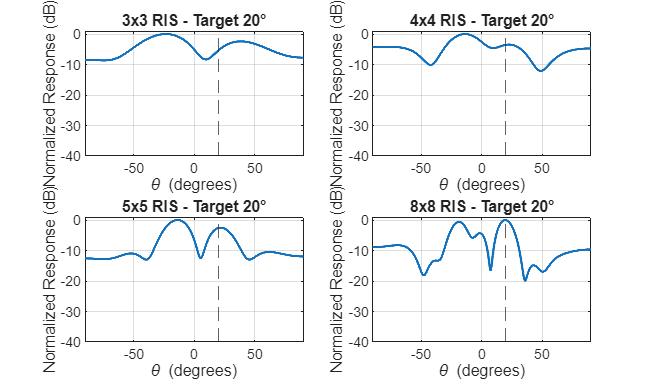


%% ================================================================
% 15. BEAM PATTERNS FOR SELECTED ARRAY SIZES
% ================================================================
%
% Compare 3x3, 4x4, 5x5 and 8x8 at 20 degrees.
%
% ================================================================

comparisonSizes = [3 4 5 8];
comparisonAngle = 20;

figure;

for q = 1:length(comparisonSizes)

    N = comparisonSizes(q);

    % Find array index
    a = find(arraySizes == N);

    % Find steering index
    s = find(steeringAngles == comparisonAngle);

    % Recalculate pattern for plotting
    x = ((0:N-1)-(N-1)/2)*dx;

    desiredPhase = ...
        -k*x*sin(deg2rad(comparisonAngle));

    state = zeros(N,N);

    for m = 1:N

        phi_required = desiredPhase(m);

        errorON = abs(angle( ...
            exp(1j*(phi_required - ...
            angle(Gamma_ON_realistic)))));

        errorOFF = abs(angle( ...
            exp(1j*(phi_required - ...
            angle(Gamma_OFF_realistic)))));

        if errorON <= errorOFF
            state(m,:) = 1;
        else
            state(m,:) = 0;
        end

    end

    AF = zeros(size(theta));

    for m = 1:N

        for n = 1:N

            if state(m,n) == 1
                Gamma = Gamma_ON_realistic;
            else
                Gamma = Gamma_OFF_realistic;
            end

            AF = AF + ...
                Gamma .* exp( ...
                1j*k*x(m)*sin(thetaRad));

        end

    end

    AFmag = abs(AF);
    AFmag = AFmag/max(AFmag);

    AFdB = 20*log10(AFmag+eps);

    subplot(2,2,q);

    plot(theta,AFdB,'LineWidth',1.5);

    hold on;

    xline(comparisonAngle,'--');

    grid on;

    xlim([-90 90]);
    ylim([-40 1]);

    xlabel('\theta (degrees)');
    ylabel('Normalized Response (dB)');

    title(sprintf('%dx%d RIS - Target %d°', ...
        N,N,comparisonAngle));

end

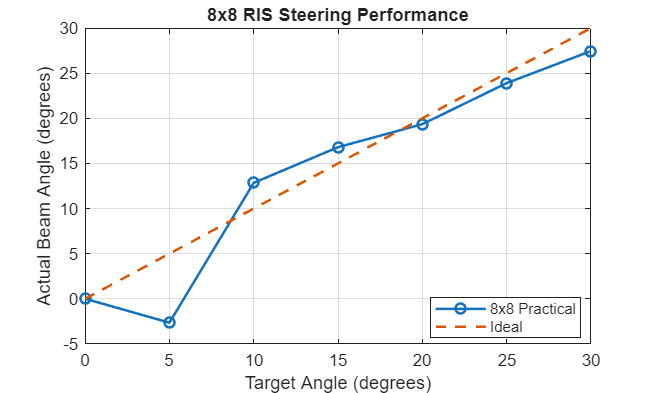


%% ================================================================
% 16. 8x8 PERFORMANCE AT DIFFERENT STEERING ANGLES
% ================================================================

N = 8;
a = find(arraySizes == N);

figure;

plot(steeringAngles, ...
    desiredAngle_real(a,:), ...
    '-o', ...
    'LineWidth',1.5, ...
    'DisplayName','8x8 Practical');

hold on;

plot(steeringAngles, ...
    steeringAngles, ...
    '--', ...
    'LineWidth',1.5, ...
    'DisplayName','Ideal');

grid on;

xlabel('Target Angle (degrees)');
ylabel('Actual Beam Angle (degrees)');

title('8x8 RIS Steering Performance');

legend('Location','best');


%% ================================================================
% 17. ARRAY APERTURE / PHYSICAL SIZE
% ================================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('PHYSICAL ARRAY SIZE\n');

PHYSICAL ARRAY SIZE


fprintf('============================================================\n');


fprintf('\n');
fprintf('Array    Active Pitch Span    Approx. Cell Footprint\n');

Array    Active Pitch Span    Approx. Cell Footprint


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------



for a = 1:numArrays

    N = arraySizes(a);

    pitchSpan = (N-1)*dx*1000;
    approximateFootprint = N*dx*1000;

    fprintf('%dx%-2d     %8.1f mm             %8.1f mm\n', ...
        N,N,pitchSpan,approximateFootprint);

end

2x2          60.0 mm                120.0 mm
3x3         120.0 mm                180.0 mm
4x4         180.0 mm                240.0 mm
5x5         240.0 mm                300.0 mm
6x6         300.0 mm                360.0 mm
7x7         360.0 mm                420.0 mm
8x8         420.0 mm                480.0 mm



%% ================================================================
% 18. EXPORT RESULTS TO CSV
% ================================================================

summaryTable = table( ...
    arraySizes(:), ...
    (arraySizes(:)).^2, ...
    meanError, ...
    maxError, ...
    meanPenalty, ...
    maxPenalty, ...
    meanSLL, ...
    passPercent, ...
    'VariableNames', ...
    {'ArraySize','Elements','MeanError_deg', ...
     'MaxError_deg','MeanGlobalPenalty_dB', ...
     'MaxGlobalPenalty_dB','MeanSLL_dB', ...
     'PassPercent'});

writetable(summaryTable, ...
    'RIS_Array_Validation_Summary.csv');

fprintf('\n');
fprintf('Results exported to:\n');

Results exported to:


fprintf('RIS_Array_Validation_Summary.csv\n');

RIS_Array_Validation_Summary.csv



%% ================================================================
% 19. OPTIONAL HFSS 2x2 VALIDATION
% ================================================================
%
% Export your HFSS angular RCS data as CSV.
%
% Recommended format:
%
% HFSS_2x2_RCS.csv
%
% Column 1 = Theta_deg
% Column 2 = RCS_ON_dB
% Column 3 = RCS_OFF_dB
%
% Example:
%
% Theta_deg,RCS_ON_dB,RCS_OFF_dB
% -90,-35.2,-34.8
% -89,-34.9,-34.5
% ...
%
% Then set:
%
% useHFSS2x2 = true;
%
% ================================================================

useHFSS2x2 = false;

if useHFSS2x2

    data = readtable('HFSS_2x2_RCS.csv');

    thetaHFSS = data.Theta_deg;

    RCS_ON_HFSS = data.RCS_ON_dB;
    RCS_OFF_HFSS = data.RCS_OFF_dB;

    figure;

    plot(thetaHFSS,RCS_ON_HFSS, ...
        'LineWidth',1.5, ...
        'DisplayName','HFSS ON');

    hold on;

    plot(thetaHFSS,RCS_OFF_HFSS, ...
        'LineWidth',1.5, ...
        'DisplayName','HFSS OFF');

    grid on;

    xlabel('\theta (degrees)');
    ylabel('RCS (dB)');

    title('2x2 HFSS RCS Validation');

    legend('Location','best');

end

%% ================================================================
% 20. FINAL MESSAGE
% ================================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('VALIDATION STUDY COMPLETE\n');

VALIDATION STUDY COMPLETE


fprintf('============================================================\n');


fprintf('\n');
fprintf('Important:\n');

Important:


fprintf('The MATLAB model is an analytical array-factor model.\n');

The MATLAB model is an analytical array-factor model.


fprintf('It does NOT replace full-wave HFSS simulation.\n');

It does NOT replace full-wave HFSS simulation.


fprintf('Use the selected array size as the candidate for HFSS.\n');

Use the selected array size as the candidate for HFSS.


fprintf('Then compare HFSS beam angle, RCS and sidelobes.\n');

Then compare HFSS beam angle, RCS and sidelobes.



fprintf('\n');

%% ================================================================
% LOCAL FUNCTION: HPBW
% ================================================================

function HPBW = calculateHPBW(theta,AFdB,peakIndex)

    peakValue = AFdB(peakIndex);

    halfPowerLevel = peakValue - 3;

    % Search left
    leftIndex = peakIndex;

    while leftIndex > 1 && ...
            AFdB(leftIndex) > halfPowerLevel

        leftIndex = leftIndex - 1;

    end

    % Search right
    rightIndex = peakIndex;

    while rightIndex < length(AFdB) && ...
            AFdB(rightIndex) > halfPowerLevel

        rightIndex = rightIndex + 1;

    end

    if leftIndex > 1 && rightIndex < length(AFdB)

        HPBW = ...
            theta(rightIndex) - theta(leftIndex);

    else

        HPBW = NaN;

    end

end